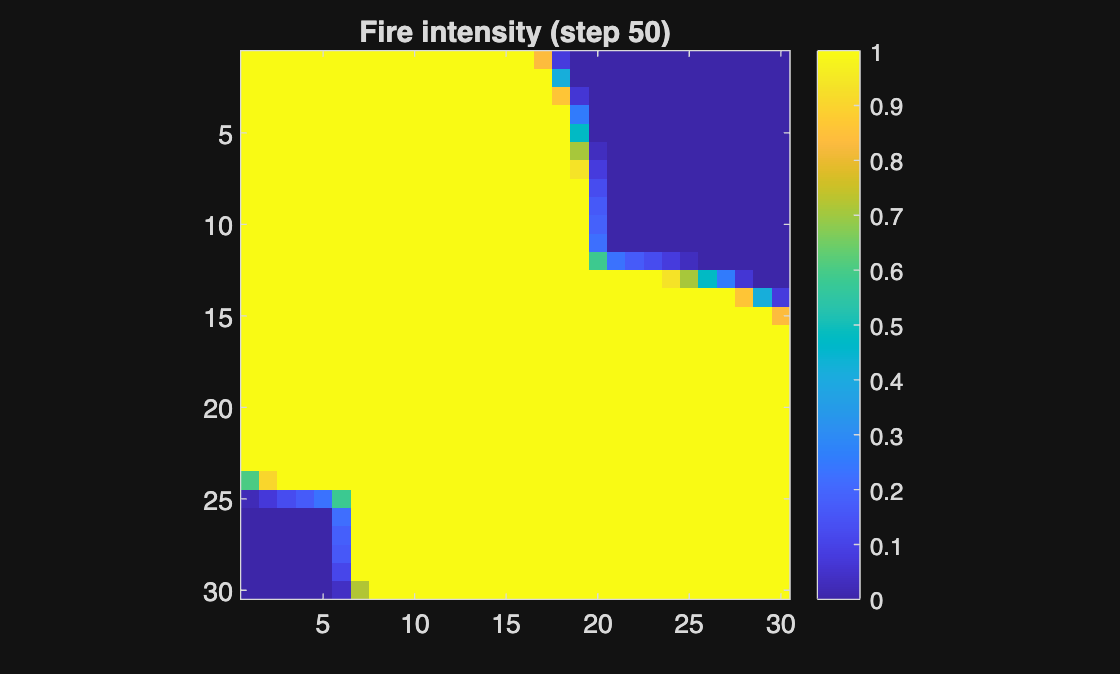

clear; clc; close all;

% -----------------------------
% Define parameters
% -----------------------------

params.rows = 30;
params.cols = 30;

% Start fires at two points
params.starting_fires = [ 10 5; 27 21]; % starting location 
params.start_intensity = 1; % intensity

% Fire dynamics
params.spread_rate = 0.2;  % spreads to neighbors
params.decay_rate = 0.05;  % fire fades per step

% Simulation control
params.max_steps = 50;     % run per steps / time span
params.display = true;     % visualization if true

% -----------------------------
% Initialize the fire
% -----------------------------
fire = init_fire(params);

% -----------------------------
% Simulation loop
% -----------------------------
for time = 1:params.max_steps
    fire = fire_step(fire, params);

    % visualization
    if params.display
        imagesc(fire.intensity, [0 1]);
        axis equal tight;
        colorbar;
        title(sprintf('Fire intensity (step %d)', time));
        drawnow;
    end

    % stopping condition: all cells nearly extinguished
    if max(fire.intensity(:)) < 0.1
        fprintf('Fire extinguished after %d steps.\n', time);
        break;
    end
end


disp('Simulation complete.');

Simulation complete.
